Ts            = 0.01; 

Mountain road

load('E:\HK\RA\Vehicle dynamics\Matlab\SystemIdentification\CarSim outputs\With Cargo\LastRunmountainRoad.mat')
% Vy = -Vy;
[Vx, Vy, delta, AV_Y] = convertUnits(Vx, Vy, Steer_R1, Steer_L1, AV_Y);
AV_R = deg2rad(AV_R); Roll = deg2rad(Roll); Ax = Ax*9.81; PtchGnd = deg2rad(PtchGnd);
data{1} = iddata(Vx, [Throttle, PtchGnd], Ts);
data{1}.InputName = {'throttle', 'PtchGnd'};
data{1}.OutputName = {'vx'};

Lane keeping

load('E:\HK\RA\Vehicle dynamics\Matlab\SystemIdentification\CarSim outputs\With Cargo\LastRunLaneKeeping.mat')
% Vy = -Vy;
[Vx, Vy, delta, AV_Y] = convertUnits(Vx, Vy, Steer_R1, Steer_L1, AV_Y);
AV_R = deg2rad(AV_R); Roll = deg2rad(Roll); Ax = Ax*9.81; PtchGnd = deg2rad(PtchGnd);
data{2} = iddata(Vx, [Throttle, PtchGnd], Ts);
data{2}.InputName = {'throttle', 'PtchGnd'};
data{2}.OutputName = {'vx'};

dataMerge = merge(data{1},data{2})

dataMerge =
Time domain data set containing 2 experiments.

Experiment     Samples      Sample Time        
   Exp1         17233            0.01          
   Exp2         15043            0.01          
                                               
Outputs        Unit (if specified)             
   vx                                          
                                               
Inputs         Unit (if specified)             
   throttle                                    
   PtchGnd                                     
                                               



dataMerge.exp = {'Mountain road', 'Roll 60km/h'};
dataMerge = data{1};

System identification Grey-box


FileName      = 'ODELongiModel';       % File describing the model structure.
Order         = [1 2 1];           % Model orders [ny nu nx].
Parameters    = [4000;
                 0.3;
                 2.2;
                 1270+142+250;];         % Initial parameters.
% C_thro, C_D, A, m

InitialStates = [0];            % Initial initial states.
            
nlgr = idnlgrey(FileName, Order, Parameters, InitialStates, Ts, ...
                'Name', 'SingleTrackModel');

nlgr.SimulationOptions.AbsTol = 1e-6;
nlgr.SimulationOptions.RelTol = 1e-5;


% nlgr.Parameters(1).Fixed = true;
nlgr.Parameters(2).Fixed = true;
nlgr.Parameters(3).Fixed = true;
nlgr.Parameters(4).Fixed = true;


nlgr = setinit(nlgr, 'Fixed', {false}); % Estimate the initial states.
size(nlgr)

Nonlinear grey-box model with 1 outputs, 2 inputs, 1 states and 4 parameters (1 free).


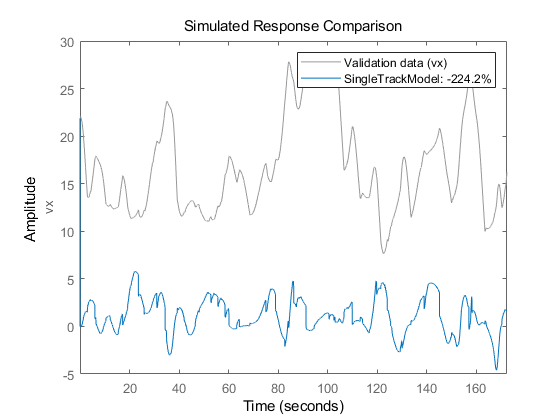


compare(data{1}, nlgr);

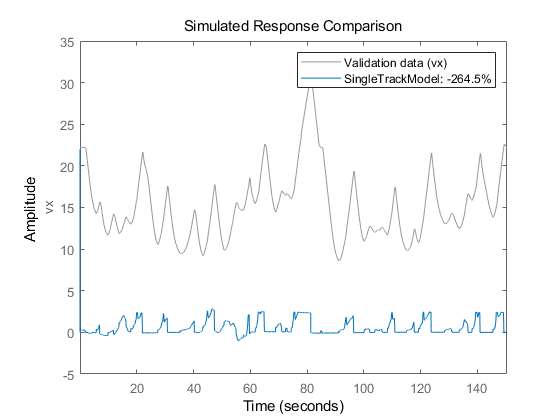

compare(data{2}, nlgr);


% nlgr = setinit(nlgr, 'Fixed', {false false}); % Estimate the initial states.
opt = nlgreyestOptions('Display', 'on');

opt.SearchOptions.MaxIterations = 50;

% opt.GradientOptions.Type = 'Refined';

% opt.OutputWeight = [0 0 0 0;
%                     0 0 0 0;
%                     0 0 1 0;
%                     0 0 0 0];

nlgr = nlgreyest(dataMerge, nlgr, opt);

fprintf('Trained model:')

Trained model:

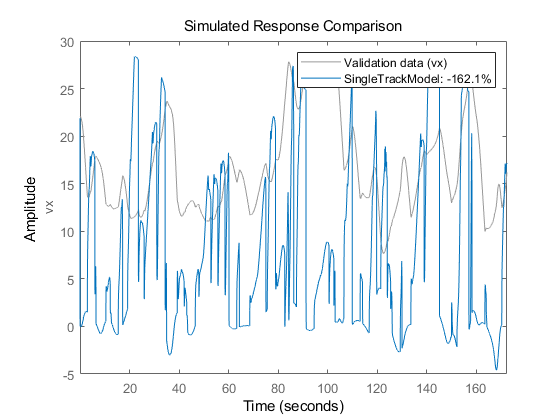

compare(data{1}, nlgr);

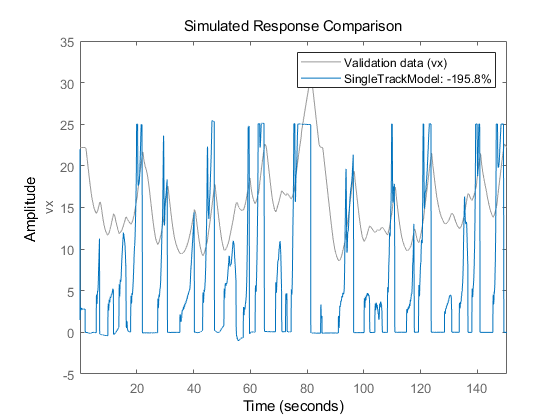

compare(data{2}, nlgr);


params_est = nlgr.Parameters;

Detection

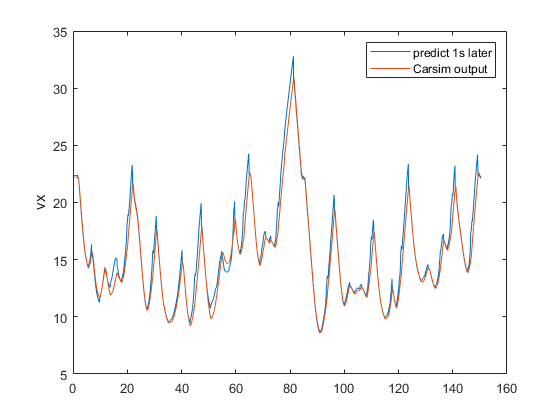

y_1s = zeros([length(data{2}.y),1]);
for i = 1:length(data{2}.y)
    [t,y] = ode45(@(t,y) ODELongiModel2(t, y, data{2}.u(i,:),...
        4000, params_est(2).Value, params_est(3).Value,...
        params_est(4).Value), [0 1], data{2}.y(i,:));
    
    y_1s(i) = y(end,1);
end

figure
plot(Time, y_1s)
hold on
plot(Time, data{2}.y)
legend('predict 1s later', 'Carsim output')
ylabel('vx')